Name    : Pranay Borgohain

Roll No. : 20EE01015

# **Digital Signal Processing Laboratory Experiment - 5**

% Defining some common functions to be used in this experiment

% making the value of heaviside() at origin equal to 1
sympref('HeavisideAtOrigin', 1);
u = @(n) heaviside(n);

% defining the DTFT function
dtft = @(xn, n, w) xn * exp(-1j .* (n' * w));

% defining the DFT function
dft = @(xn, n) xn * exp((-1j * 2*pi/length(n)) .* (n' * (0:(length(n)-1))));

% defining range of frequencies (omega) from -pi to +pi
w = 0:0.01:(2*pi);

% Defining the circfold function
circfold = @(x1, N) dft(dft([x1 zeros(1, N-length(x1))], 0:(N-1)), 0:(N-1)) ./ N;

% The interpolate() function for Q2 is defined at the end of this file.

Q1:

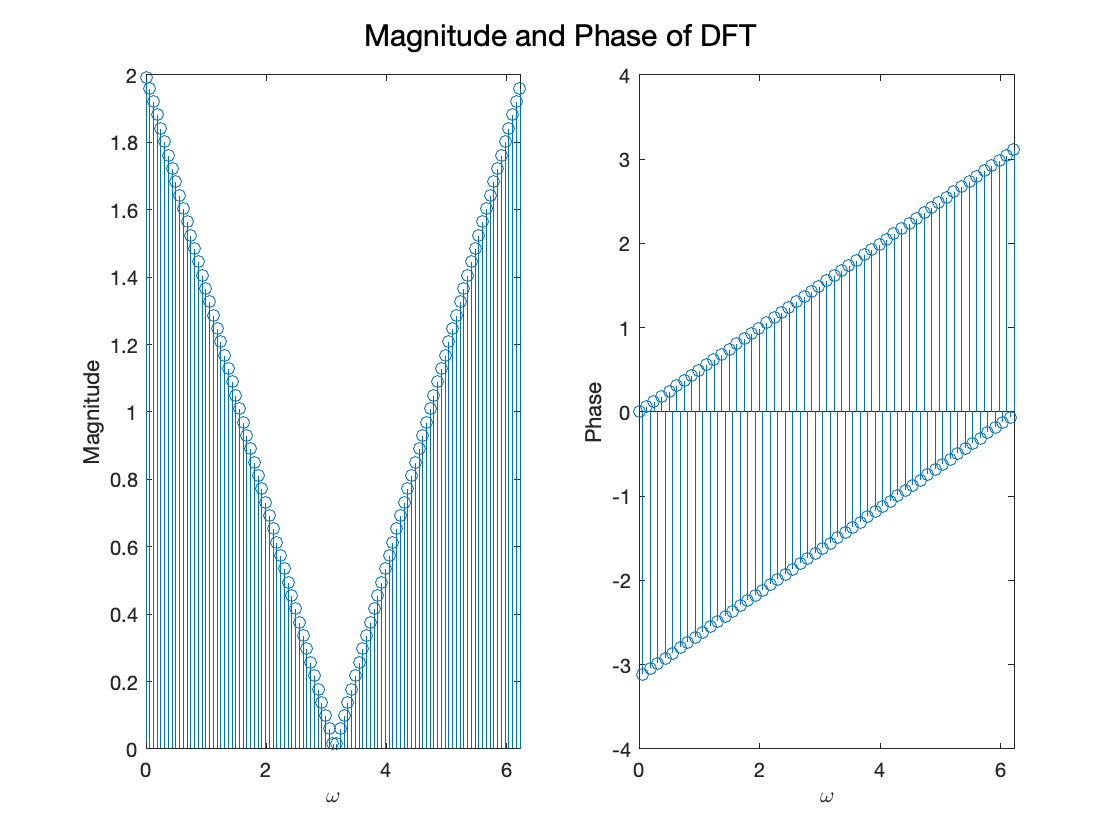

% Defining the signal x(n)
x = @(n) ((sinc((n-50)/2)).^2) .* (u(n) - u(n-100.01));

n = 0:100;

% (a) Plotting the DFT of x(n)
X_dft = dft(x(n), n);

% indices of DFT
k = (2*pi/length(n)) .* (0:(length(n) - 1));

figure;
subplot(1, 2, 1);
stem(k, abs(X_dft));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Magnitude");
subplot(1, 2, 2);
stem(k, angle(X_dft));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Phase");
sgtitle("Magnitude and Phase of DFT");

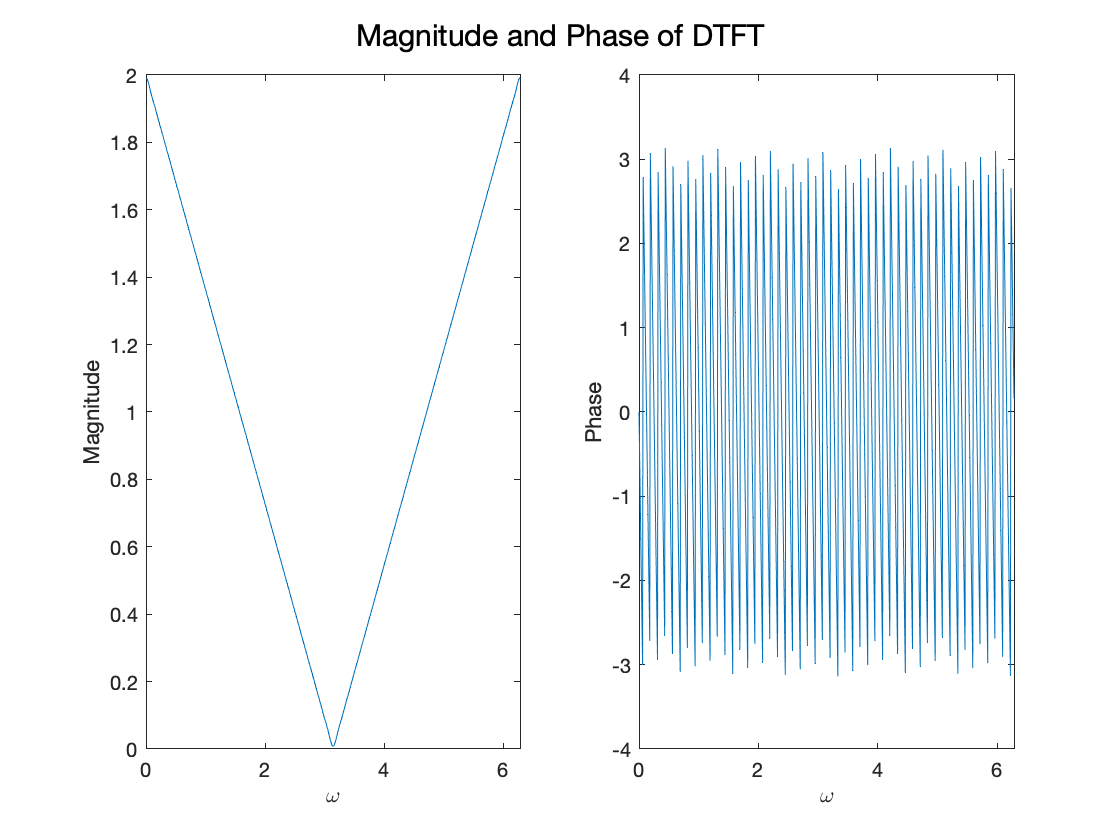

% (b) Plotting the DTFT of x(n)
X_dtft = dtft(x(n), n, w);

figure;
subplot(1, 2, 1);
plot(w, abs(X_dtft));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Magnitude");
subplot(1, 2, 2);
plot(w, angle(X_dtft));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Phase");
sgtitle("Magnitude and Phase of DTFT");

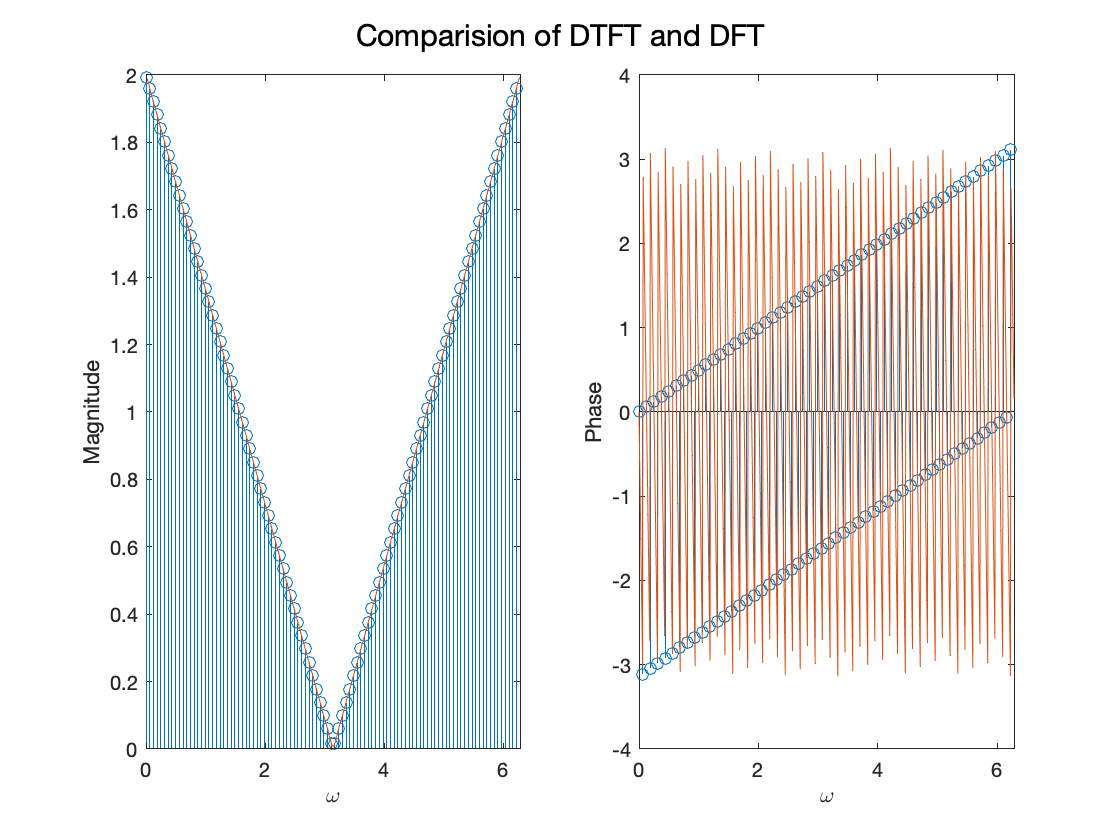

% (c) Combining the plots of DFT and DTFT to compare them
figure;
subplot(1, 2, 1);
stem(k, abs(X_dft));
hold("on");
plot(w, abs(X_dtft));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Magnitude");
subplot(1, 2, 2);
stem(k, angle(X_dft));
hold("on");
plot(w, angle(X_dtft));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Phase");
sgtitle("Comparision of DTFT and DFT");

Hence, it has been verified from the above plots that the DFT is a sampled version of the DTFT.

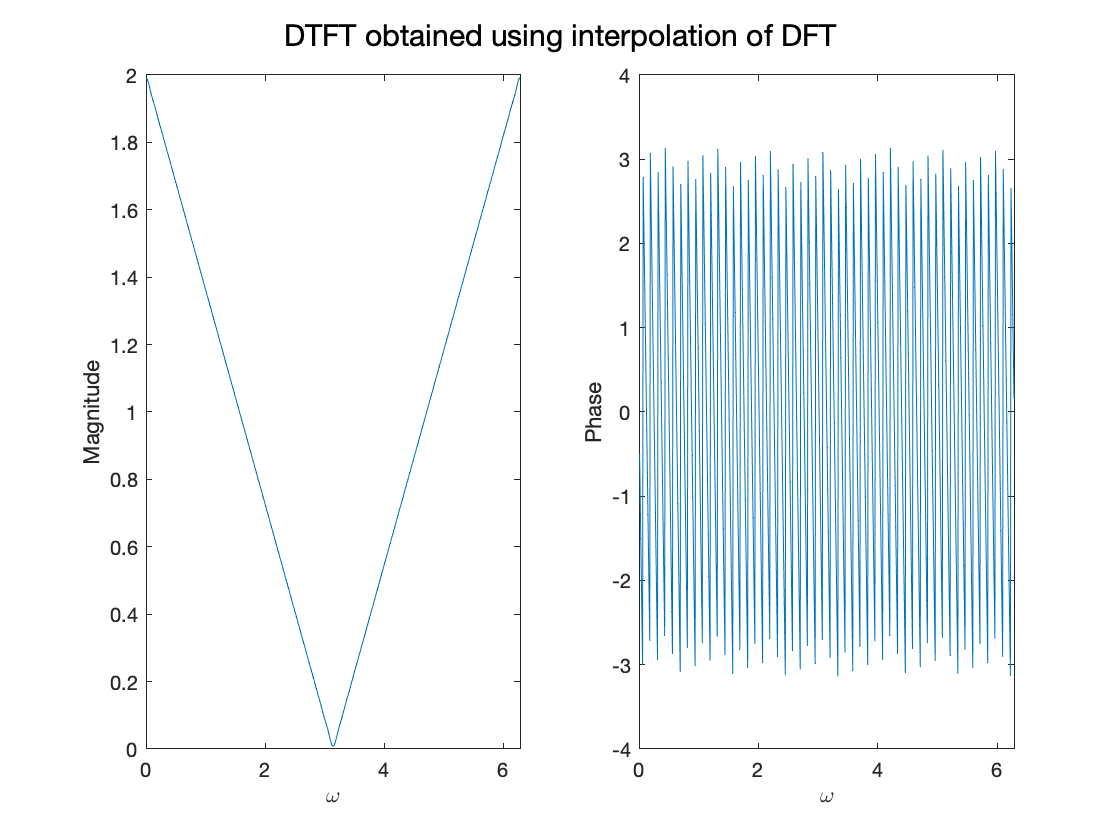

% (d) Interpolation
X_dft2 = dft(x(n), n);

X_dtft_interpolated = interpolate(X_dft2, w);

figure;
subplot(1, 2, 1);
plot(w, abs(X_dtft_interpolated));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Magnitude");
subplot(1, 2, 2);
plot(w, angle(X_dtft_interpolated));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Phase");
sgtitle("DTFT obtained using interpolation of DFT");

The DTFT of $x\left(n\right)$ has been recovered successfully using the interpolation of the DFT, and is nearly identical to the DTFT obtained using the DTFT algorithm.

Q2:

x1 = [1, 3, 5, 7, 9, -7, -5, -3, -1];

x2 = circfold(x1, 9);
disp(x2);

  Columns 1 through 2

   1.0000 + 0.0000i  -1.0000 - 0.0000i

  Columns 3 through 4

  -3.0000 - 0.0000i  -5.0000 - 0.0000i

  Columns 5 through 6

  -7.0000 - 0.0000i   9.0000 + 0.0000i

  Columns 7 through 8

   7.0000 + 0.0000i   5.0000 + 0.0000i

  Column 9

   3.0000 + 0.0000i



Q3:

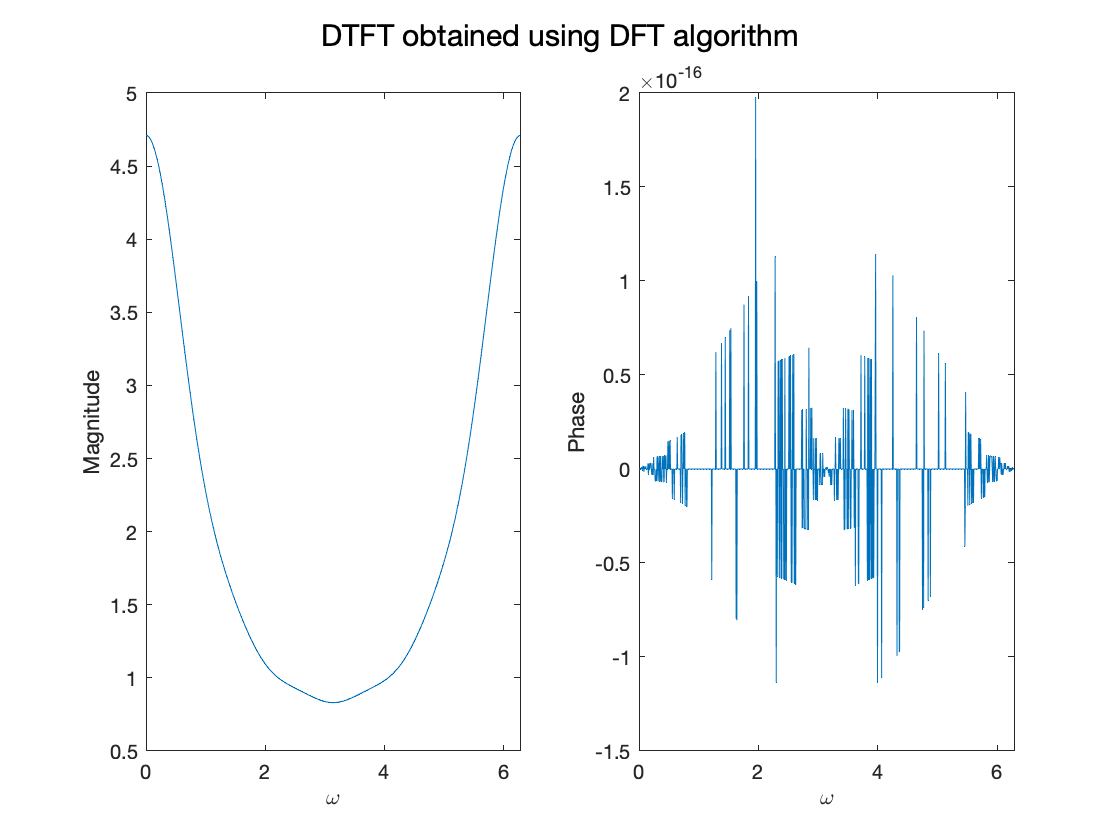

% Defining the function x(n)
x = @(n) 2 .* exp(-0.9 .* abs(n)) .* (u(n + 5) - u(n-5.01));

% Choosing N = 1001 for obtaining a smooth graph
n = -500:500;
k = (2*pi/length(n)) .* (0:(length(n) - 1));
X_dtft = dft(x(n), n);

figure;
subplot(1, 2, 1);
plot(k, abs(X_dtft));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Magnitude");
subplot(1, 2, 2);
plot(k, angle(X_dtft));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Phase");
sgtitle("DTFT obtained using DFT algorithm");

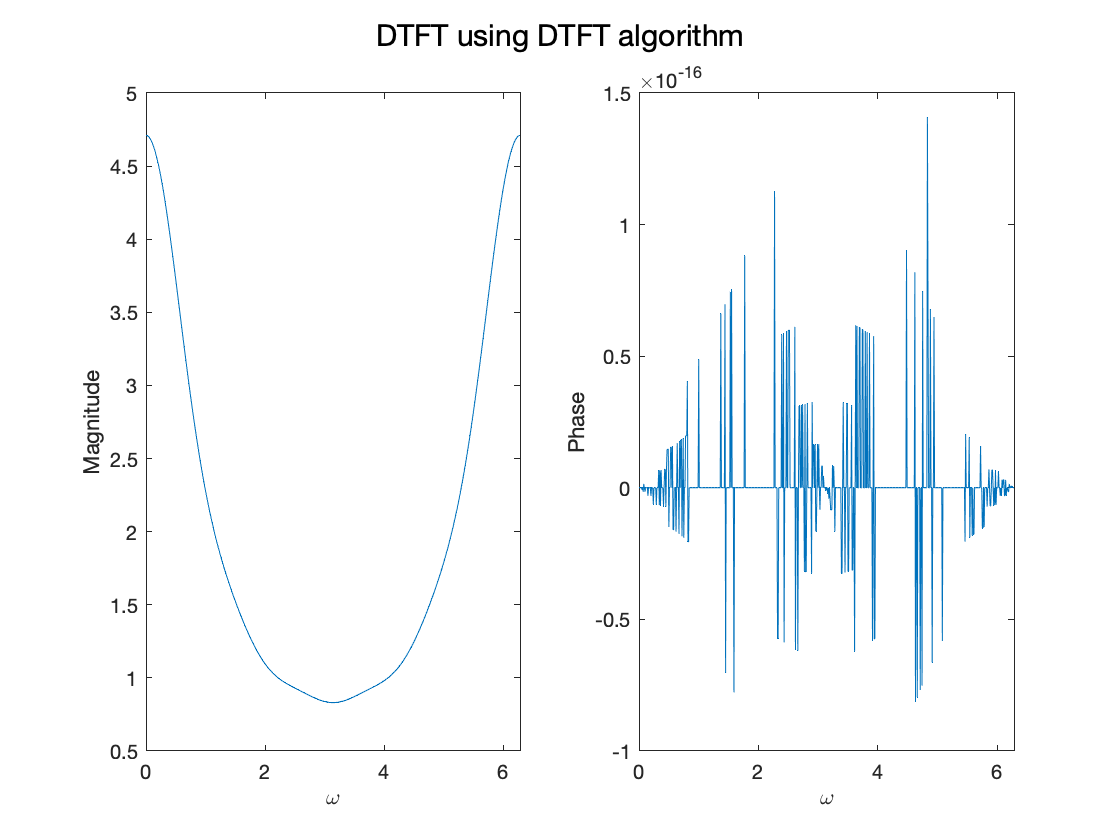

X = dtft(x(n), n, w);

figure;
subplot(1, 2, 1);
plot(w, abs(X));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Magnitude");
subplot(1, 2, 2);
plot(w, angle(X));
xlabel("$\omega$", "Interpreter", "latex"); ylabel("Phase");
sgtitle("DTFT using DTFT algorithm");

By choosing the length N of the DFT to be 1001, a smooth plot for the DTFT of $x\left(n\right)$ is obtained. The accuracy of this plot can be verified by comparing it with the plot of DTFT which is obtained using the DTFT function, as both the plots are similar.

function [xw] = interpolate(xk, w)
% defining the interpolation function
    N = length(xk);
    k = (2*pi/N) .* (0:(N - 1));

    k_matrix = k' * ones(1, length(w));
    w_matrix = ones(N, 1) * w;
    
    denominator_mat = (k_matrix) - (w_matrix);
    numerator_mat = denominator_mat .* N;
    
    S = (1 - exp(1j .* numerator_mat))./(1 - exp(1j .* denominator_mat));
    
    xw = (1/N) .* (xk * S);
end